clear all;

fs = 44100;
T0 = 0.5;
t = 0:1/fs:0.5-1/fs;

f_clean = 1e3;

length(t)

ans = 22050


clean_tone = sin(2*pi*f_clean*t);

sample = ['.' filesep, 'whistle.wav']; 

[y, fs] = audioread(sample);
T_y = length(y)/fs;

T_0 = 0.5

T_0 = 0.5000

t_start = 2.2

t_start = 2.2000


t_y = 0:1/fs:T_0-1/fs;
length(y)

ans = 184347

length(t_y)

ans = 22050


y = y(fs*t_start:fs*(t_start+T_0)-1)

y =     0.2340
    0.2231
    0.1963
    0.1663
    0.1284
    0.0887
    0.0530
    0.0268
    0.0154
   -0.0069


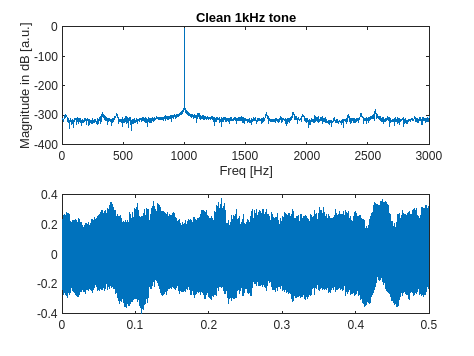


plot(t_y, y)


singing_sample = y

singing_sample =     0.2340
    0.2231
    0.1963
    0.1663
    0.1284
    0.0887
    0.0530
    0.0268
    0.0154
   -0.0069


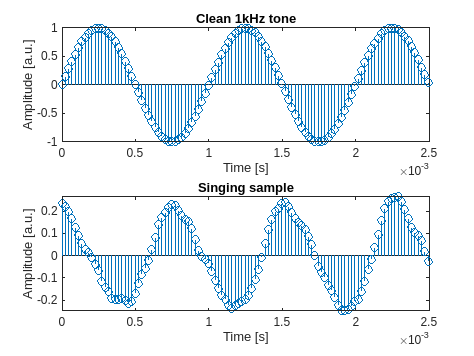

figure(1) 
subplot(2,1,1) 
stem(t, clean_tone)
xlim([0 0.0025]);

title('Clean 1kHz tone')
xlabel 'Time [s]'; 
ylabel 'Amplitude [a.u.]'; 

subplot(2,1,2) 
stem(t,singing_sample)
xlim([0 0.0025]);

title('Singing sample')
xlabel 'Time [s]'; 
ylabel 'Amplitude [a.u.]'; 

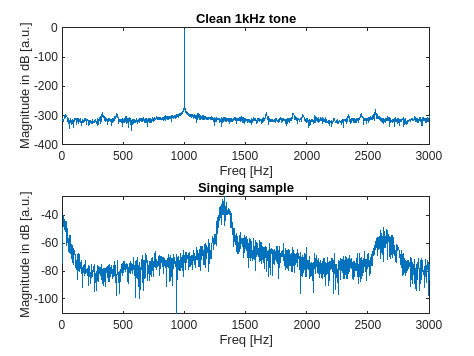

[Y_clean, freq_clean] = make_spectrum(clean_tone, fs);
clean_dB = 20*log10(abs(Y_clean));

[Y_singing, freq_singing] = make_spectrum(singing_sample, fs);
singing_dB = 20*log10(abs(Y_singing));

figure(2) 
subplot(2,1,1) 
plot(freq_clean, clean_dB)
xlim([0 3e3]);
title('Clean 1kHz tone')
xlabel 'Freq [Hz]'; 
ylabel 'Magnitude in dB [a.u.]'; 

subplot(2,1,2) 
plot(freq_singing,singing_dB)
xlim([0 3e3]);

title('Singing sample')
xlabel 'Freq [Hz]'; 
ylabel 'Magnitude in dB [a.u.]'; 

function [Y, freq] = make_spectrum(signal, fs)
    Y = fft(signal);
    Y = Y/(length(Y));
    T0 = length(signal)/fs;
    delta_f = 1/T0;
    freq = 0:delta_f:fs-delta_f;

    Y = Y(:);
    freq = freq(:);
end